clear all, close all, clc

## Prob-4.4a

Please see the other pdf of Prob-4.4a

## Prob-4.4b

Let's varify the cut-set acquired by SAPPHIRE

From RSANS Example 6.3, we get the following diagram-

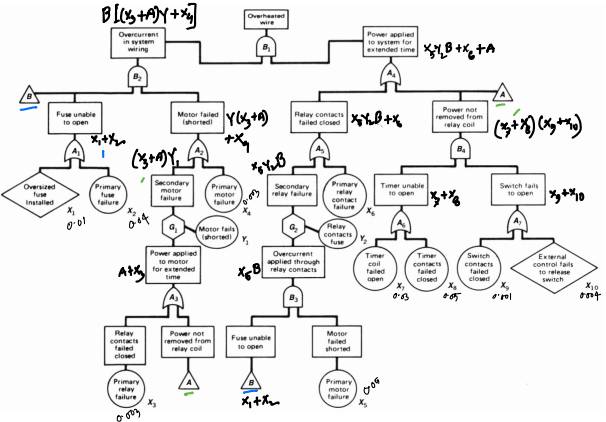

Now, just enumerate the basic events

syms y1 y2
syms x1 x2 x3 x4 x5 x6 x7 x8 x9 x10
A = (x7 + x8) *(x9 + x10);              % repeating set
B = x1 + x2;                            %
B1 = B *((x3+A)*y1 + x4) *(x5*y2*B +x6 +A)

$$B1 = \left(x_{1}+x_{2}\right)\,\left(x_{4}+y_{1}\,\left(x_{3}+\left(x_{7}+x_{8}\right)\,\left(x_{9}+x_{10}\right)\right)\right)\,\left(x_{6}+\left(x_{7}+x_{8}\right)\,\left(x_{9}+x_{10}\right)+x_{5}\,y_{2}\,\left(x_{1}+x_{2}\right)\right)$$

% B1 = expand(B2);

Now, for identical elements

y1 = x4; x5 = x4;
x6 = x3; y2 = x3;
B1 = eval(B1)               % evaluating replacing the identical events

$$B1 = \left(x_{1}+x_{2}\right)\,\left(x_{4}+x_{4}\,\left(x_{3}+\left(x_{7}+x_{8}\right)\,\left(x_{9}+x_{10}\right)\right)\right)\,\left(x_{3}+\left(x_{7}+x_{8}\right)\,\left(x_{9}+x_{10}\right)+x_{3}\,x_{4}\,\left(x_{1}+x_{2}\right)\right)$$

Then again, we have

syms A B 
B2 = B*(x4+ x4*(x3+A));
A4 = x3 + A + x3*x4*B;

Using the idempotent law, we have-


$$X\;=\;X+AX\;$$


B2 = B*x4;
A4 = A + x3;

So,

B1 = B*x4 *(A +x3)

$$B1 = B\,x_{4}\,\left(A+x_{3}\right)$$

The above is the minimal cut-set

Now, again, let's put the values of set B and A

B = x1 + x2;
A = (x7 + x8) *(x9 + x10);
B1 = eval(B1)

$$B1 = x_{4}\,\left(x_{1}+x_{2}\right)\,\left(x_{3}+\left(x_{7}+x_{8}\right)\,\left(x_{9}+x_{10}\right)\right)$$

So, the expansion of the cutset is like-

B1 = expand(B1)

$$B1 = x_{1}\,x_{3}\,x_{4}+x_{2}\,x_{3}\,x_{4}+x_{1}\,x_{4}\,x_{7}\,x_{9}+x_{1}\,x_{4}\,x_{7}\,x_{10}+x_{1}\,x_{4}\,x_{8}\,x_{9}+x_{2}\,x_{4}\,x_{7}\,x_{9}+x_{1}\,x_{4}\,x_{8}\,x_{10}+x_{2}\,x_{4}\,x_{7}\,x_{10}+x_{2}\,x_{4}\,x_{8}\,x_{9}+x_{2}\,x_{4}\,x_{8}\,x_{10}$$

This correponds the following diagram-

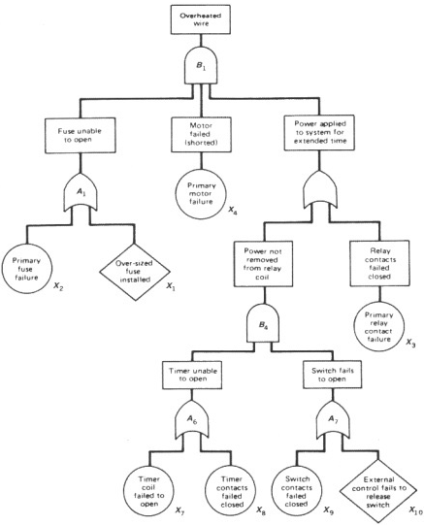

Now, let's evaluate the probabilities,

x1 = 0.01;      % oversized fuse installed
x2 = 0.04;      % primary fuse failure
x3 = 0.003;     % primary relay failure
x4 = 0.003;     % primary motor failure

x7 = 0.03;      % timer coil failing open
x8 = 0.05;      % timer contact failing closed
x9 = 0.001;     % switch contact failing closed
x10 = 0.004;    % external control failing to release switch

Now, let's evaluate the probability of top event B1

P_B1 = eval(B1)

P_B1 = 5.1000e-07

So, we can see, indeed, SAPPHIRE code generated right probability and cutset

(Ans)

To verify two very prominant cutset, let's view the circuit diagram once again-

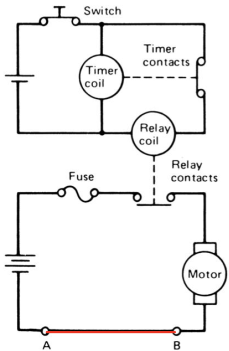


$$x_1 \,x_3 \,x_4 +x_2 \,x_3 \,x_4 +x_1 \,x_4 \,x_7 \,x_9 +x_1 \,x_4 \,x_7 \,x_{10} +x_1 \,x_4 \,x_8 \,x_9 +x_2 \,x_4 \,x_7 \,x_9 +x_1 \,x_4 \,x_8 \,x_{10} +x_2 \,x_4 \,x_7 \,x_{10} +x_2 \,x_4 \,x_8 \,x_9 +x_2 \,x_4 \,x_8 \,x_{10}$$


We can say that two most important cut-sets are $x_1 \,x_4 \,x_7 \,x_{10}$ and $x_1 \,x_3 \,x_4$

To calculate their probabilities-

C1 = x1 *x3 *x4

C1 = 9.0000e-08

C2 = x1 *x4 *x7 *x10

C2 = 3.6000e-09

## Prob-4.4c

Now, let's do it for 5th percentile value-

z1 = norminv(0.05)       % z-score for 05-th percentile

z1 = -1.6449

z2 = norminv(0.95)       % z-score for 95-th percentile

z2 = 1.6449

Now, we know two things

$\frac{x_1 -\mu }{x_2 -\mu }=\frac{z_1 }{z_2 }$    Here, $\mu \;$is the mean

and, $x_2 ={\textrm{ef}}^2 x_1$

These two reduces to; $x_1 =\frac{\mu \;\left(z_2 -z_1 \right)}{z_2 -{\textrm{ef}}^2 z_1 }\;$

So, we get the followings-

mu = 0.01           % mean probab' value

mu = 0.0100

ef = 2;                 % error factor

x_1 = mu*(z2 - z1)/(z2 - ef^2*z1)       % 5-th percentile value

x_1 = 0.0040

x_2 = x_1 *ef^2                         % 95th percentile value

x_2 = 0.0160

So, let's find the vector for x_1 and x_2

mu = [x1 x2 x3 x4 x7 x8 x9 x10];     % define probab' set
x_1 = mu*(z2 - z1)/(z2 - ef^2*z1)   % arrary for 5-th percentile probab' value

x_1 =     0.0040    0.0160    0.0012    0.0012    0.0120    0.0200    0.0004    0.0016


x_2 = x_1 *ef^2                     % ...95-th percentile

x_2 =     0.0160    0.0640    0.0048    0.0048    0.0480    0.0800    0.0016    0.0064


Now, let's use these values for probability values (x) that defines the top event B1 

x1 = x_1(1);      % oversized fuse installed
x2 = x_1(2);      % primary fuse failure
x3 = x_1(3);     % primary relay failure
x4 = x_1(4);     % primary motor failure

x7 = x_1(5);      % timer coil failing open
x8 = x_1(6);      % timer contact failing closed
x9 = x_1(7);     % switch contact failing closed
x10 = x_1(8);    % external control failing to release switch

So, hereby, the 5th-percentile probab' of B1

P_B1_1 = eval(B1)

P_B1_1 = 3.0336e-08

Again, assign the x values for 95th percentile probab' of basic events-

x1 = x_2(1);      % oversized fuse installed
x2 = x_2(2);      % primary fuse failure
x3 = x_2(3);     % primary relay failure
x4 = x_2(4);     % primary motor failure

x7 = x_2(5);      % timer coil failing open
x8 = x_2(6);      % timer contact failing closed
x9 = x_2(7);     % switch contact failing closed
x10 = x_2(8);    % external control failing to release switch

Likewise, 95th-percentile probab' of B1

P_B1_2 = eval(B1)

P_B1_2 = 2.2364e-06